# **PD：GRU**

# **PA1：GRU**

# **PA2：GRU**

# **PA3：GRU**

# **PA4：GRU**

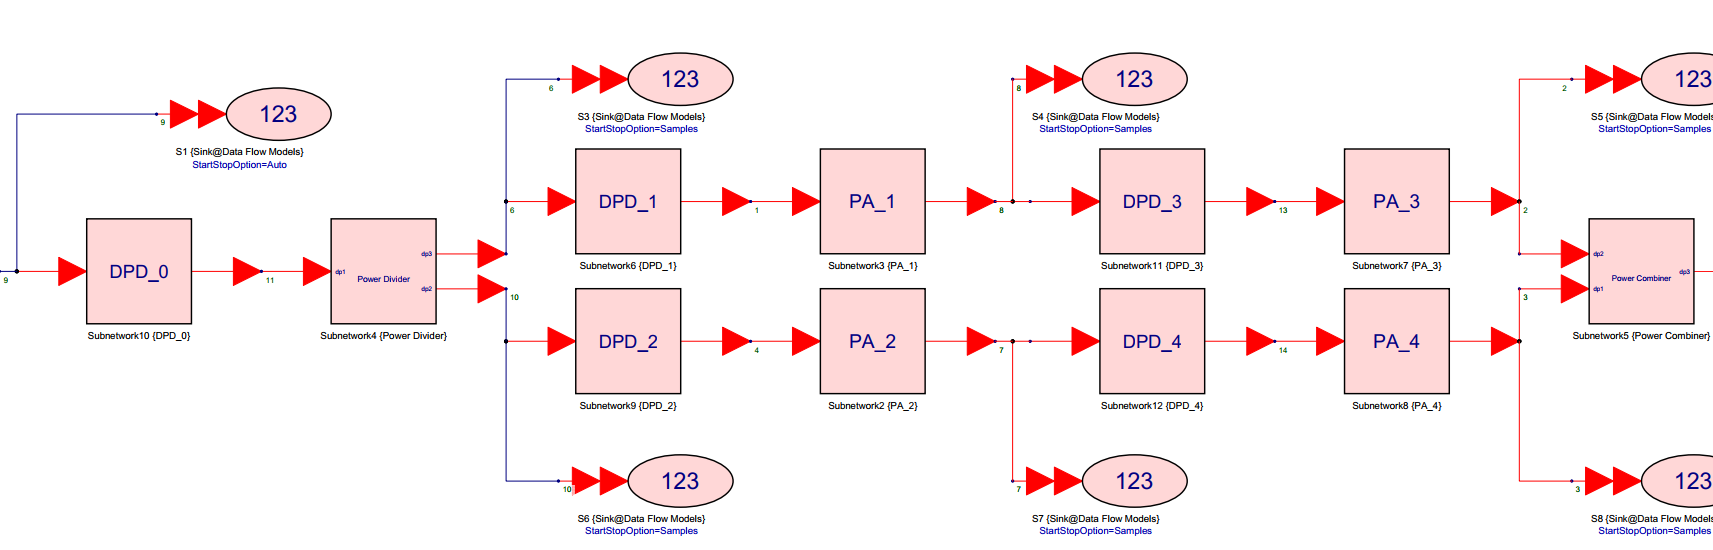

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end);
% 模型仿真
[U1,D1]=Power_Divider(Sys_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-13 *

    0.0037
    0.0030
    0.0057
    0.0049
    0.0051
    0.0050
    0.0098
    0.0063
    0.0109
    0.0111


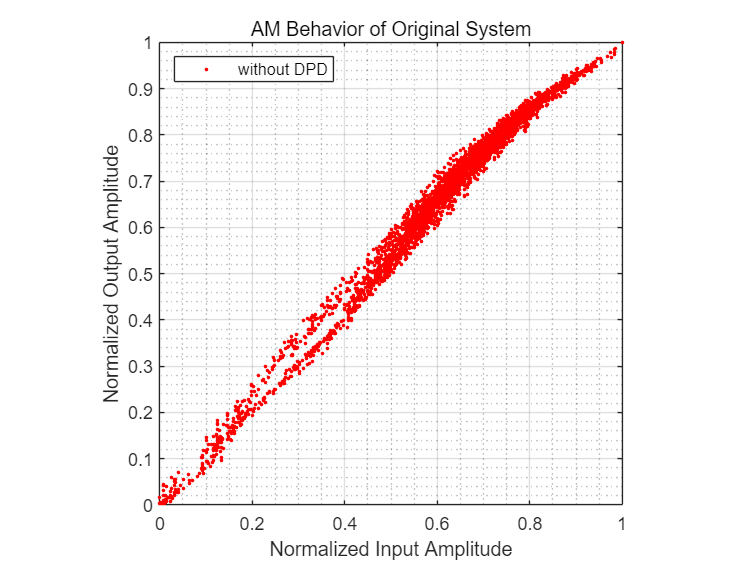

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);

## 训练PA1

% PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
% PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);
% 
% M=7; % Memory Depth
% % GRU=GRU_train(PA1_x_i,PA1_x_q,PA1_y_i,PA1_y_q,M);
% % save('Algorithm_B\Alg_PA1.mat', 'GRU','-append');

## 训练PA2

% % 根据需要选取原始数据
% PA2_x_i=Data_matrix(:,5);PA2_x_q=Data_matrix(:,6);
% PA2_y_i=Data_matrix(:,9);PA2_y_q=Data_matrix(:,10);
% 
% % GRU=GRU_train(PA2_x_i,PA2_x_q,PA2_y_i,PA2_y_q,M);
% % save('Algorithm_B\Alg_PA2.mat', 'GRU','-append');

## 第一次模拟迭代（为训练PA3和PA4）

% [S_U1,S_D1]=Power_Divider(Sys_input);
% S_U1_DPD= DPD(S_U1,M,9,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
% S_U2    = PA_1(S_U1_DPD);
% S_U3    = PA_3(S_U2);
% S_D1_DPD= DPD(S_D1,M,9,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
% S_D2    = PA_2(S_D1_DPD);
% S_D3    = PA_4(S_D2);

## 训练PA3

% PA3_x_i=real(S_U2);PA3_x_q=imag(S_U2);
% PA3_y_i=real(S_U3);PA3_y_q=imag(S_U3);
% 
% % GRU=GRU_train(PA3_x_i,PA3_x_q,PA3_y_i,PA3_y_q,M);
% % save('Algorithm_B\Alg_PA3.mat', 'GRU','-append');

## 训练PA4

% PA4_x_i=real(S_D2);PA4_x_q=imag(S_D2);
% PA4_y_i=real(S_D3);PA4_y_q=imag(S_D3);
% 
% % GRU=GRU_train(PA4_x_i,PA4_x_q,PA4_y_i,PA4_y_q,M);
% % save('Algorithm_B\Alg_PA4.mat', 'GRU','-append');

## 第二次模拟迭代（为训练PD）

M=7;
[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD(S_U1,M,9,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U2_DPD= DPD(S_U2,M,9,'Algorithm_B\Alg_PA3.mat');% input,记忆深度,不同算法,不同位置
S_U3    = PA_3(S_U2_DPD);
S_D1_DPD= DPD(S_D1,M,9,'Algorithm_B\Alg_PA2.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D2_DPD= DPD(S_D2,M,9,'Algorithm_B\Alg_PA4.mat');% input,记忆深度,不同算法,不同位置
S_D3    = PA_4(S_D2_DPD);
Sys_output_train=Power_Combiner(S_U3,S_D3);

## 训练PD

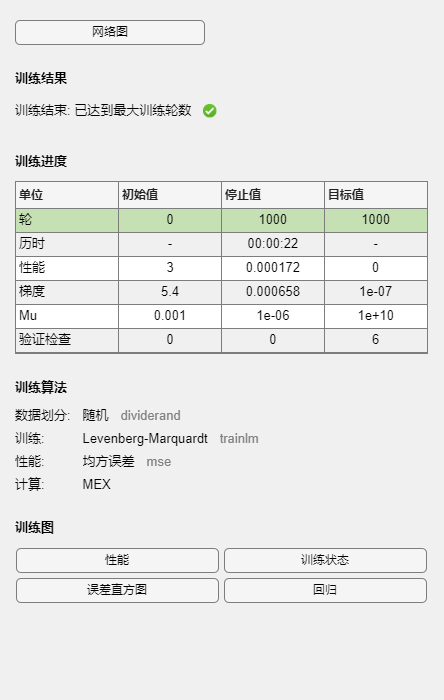

PD_x_i=real(Sys_input);PD_x_q=imag(Sys_input);
PD_y_i=real(Sys_output_train);PD_y_q=imag(Sys_output_train);

FNN_B5=FNN_train(PD_x_i,PD_x_q,PD_y_i,PD_y_q,M);

save('Algorithm_B\Alg_PD.mat', 'FNN_B5','-append');

## 系统模拟

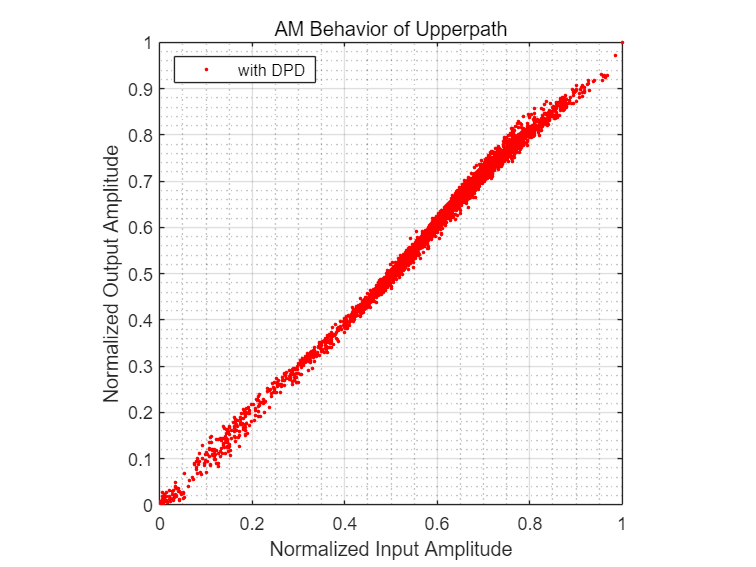

% 参数需要保持一致
M=7;
Sys_input_DPD=DPD(Sys_input,M,12,'Algorithm_B\Alg_PD.mat');
[S_U1,S_D1]=Power_Divider(Sys_input_DPD);
S_U1_DPD= DPD(S_U1,M,9,'Algorithm_B\Alg_PA1.mat');% input,记忆深度,不同算法,不同位置
S_U2    = PA_1(S_U1_DPD);
S_U2_DPD= DPD(S_U2,M,9,'Algorithm_B\Alg_PA3.mat');% input,记忆深度,不同算法,不同位置
S_U3    = PA_3(S_U2_DPD);
S_D1_DPD= DPD(S_D1,M,9,'Algorithm_B\Alg_PA2.mat');% input,记忆深度,不同算法,不同位置
S_D2    = PA_2(S_D1_DPD);
S_D2_DPD= DPD(S_D2,M,9,'Algorithm_B\Alg_PA4.mat');% input,记忆深度,不同算法,不同位置
S_D3    = PA_4(S_D2_DPD);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
Plot_AM(S_U1,S_U3,'AM Behavior of Upperpath','with DPD');

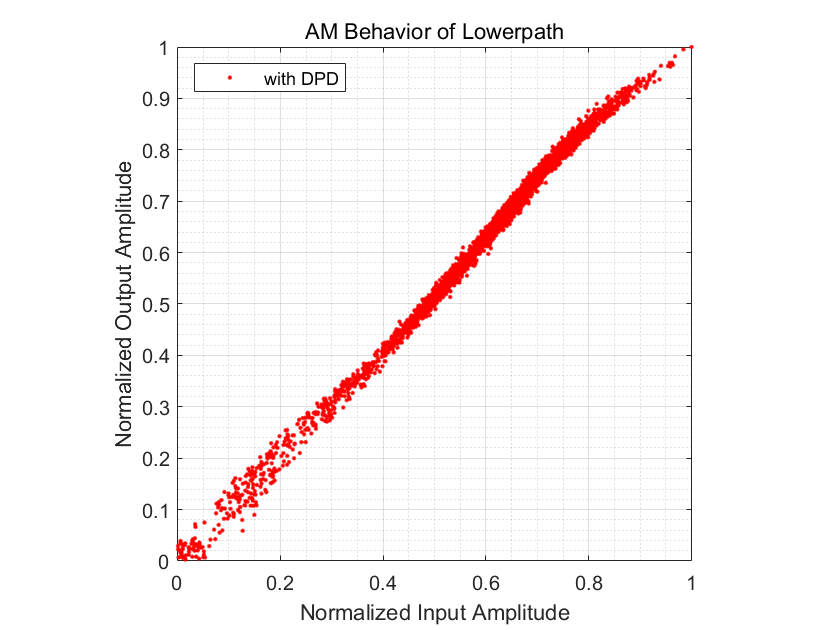

Plot_AM(S_D1,S_D3,'AM Behavior of Lowerpath','with DPD');

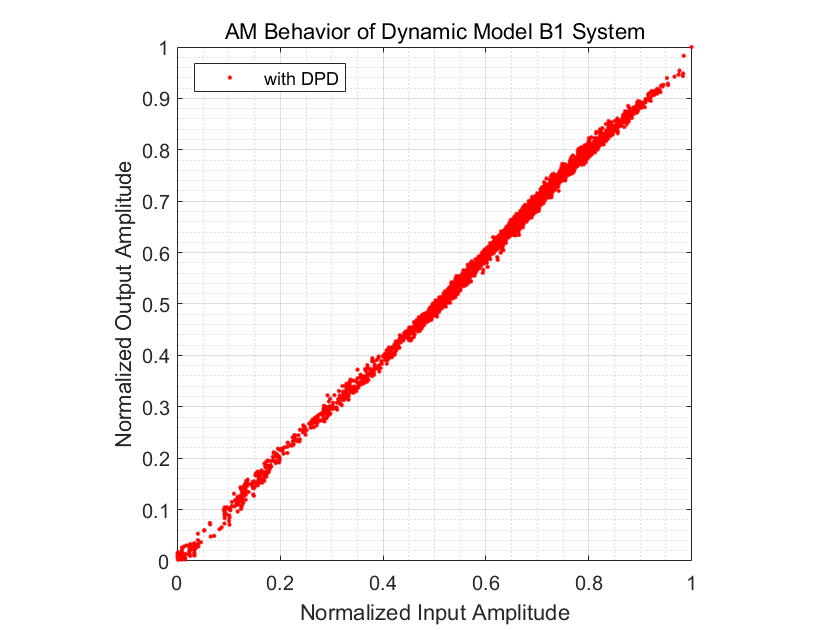

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Dynamic Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model B5，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model B5，系统的NMSE仿真结果为 -34.126977 dB
